## Rotor

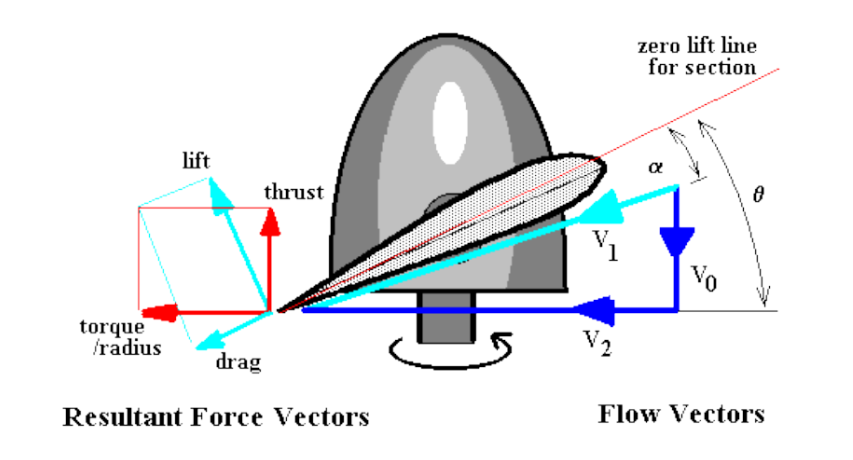

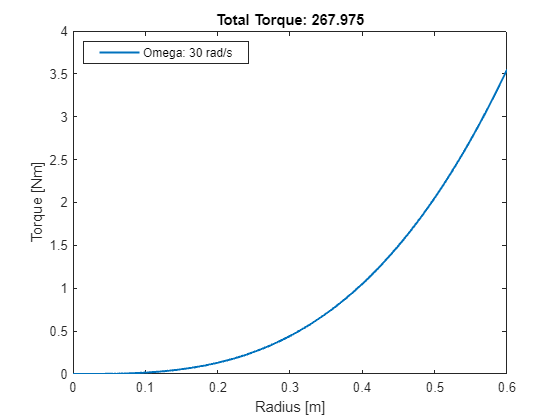

theta = 20;
alpha = 6;
rho = 1.225;

R = 0.6;    %Rotor Radius
c = 0.15;     %Rotor Chord
V1 = 0;     

B = 2;      %Number of blades
segments = 300;
r_seg = 0:R/segments:R;

torque_profile = zeros(1,length(r_seg));
thrust_profile = zeros(1,length(r_seg));
V0 = zeros(1,length(r_seg));
F= 0.05;
iterations = 25;     % Number of interation for the V01 
torque_P = zeros (iterations,length(r_seg));  
thrust_P = zeros (iterations,length(r_seg));
vortex_strength = zeros (iterations,length(r_seg));
vortex_tangentail_velcoity = zeros (1,length(r_seg));
total_torque = 0;
Torque_thrust = F*R*2;
torque_speed_curve = zeros (1,800/10);
thrust_speed_curve = zeros (1,800/10);
% all_thrust_curves = zeros(80)


for x = 10:10:800 % For loop to get thrust produceed for different omega values 

    omega = x;
    thrust_profile = zeros(1,length(r_seg));
    V02 = 0;
    for j = 1:iterations
    alpha = theta - atand(V02/(2./3.*R.*omega));
 
    for i = 1:length(r_seg)

        thrust_profile(i) = Thrust(Cl(alpha),rho,omega,r_seg(i),c,theta-alpha,Cd(alpha), B,V0(i),R/segments); % *0.98 to help account for Tip vortices
        torque_profile(i) = Torque(Cl(alpha),rho,omega,r_seg(i),c,theta-alpha,Cd(alpha), B,V0(i),R/segments);
        thrust_P(j,i)=thrust_profile(i);
        torque_P(j,i)=torque_profile(i);
    end
    total_thrust = sum(thrust_profile);
    if total_thrust < 0
        total_thrust = 0.1.*abs(total_thrust);
    end
    total_torque = sum(torque_profile(4:end));
        CT = total_thrust ./ (pi.*R.^2.*rho.*(omega.*R).^2);
    tip_loss = 1 - sqrt(2.*CT)./2;
    V02 = sqrt(total_thrust.*tip_loss/(pi * R.^2 .* rho.*2));

    end
        if alpha > 16 
            total_thrust =0;
        end
    torque_speed_curve((x/10)) = total_torque;
    thrust_speed_curve((x/10)) = total_thrust.*tip_loss;

end

plot(r_seg,torque_P(end,:), 'linewidth',1.5)
xlabel('Radius [m]');
ylabel('Torque [Nm]');
title(['Total Torque: ', num2str(total_torque)]);

legend("Omega: 30 rad/s")
legend("Position", [0.14765,0.84785,0.29684,0.053371])

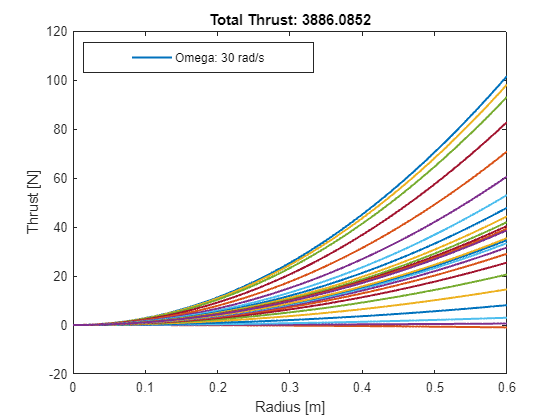


plot(r_seg,thrust_P,'linewidth',1.5) 
xlabel('Radius [m]');
ylabel('Thrust [N]');
title(['Total Thrust: ', num2str(total_thrust)]);
legend("Omega: 30 rad/s")
legend("Position", [0.14846,0.83463,0.34996,0.062966])

legend("Position", [0.14873,0.82616,0.41258,0.074286])

alpha

alpha = -1.1539

plot((10:10:200),torque_speed_curve(1:20), 'linewidth',3)
hold on
% plot((10:10:200),Torque_function(10:10:200),'--c', 'linewidth',1.5) %NEEDS TO BE COMMENTED OUT ON FIRST RUN
hold off
title("Torque Predicted vs Rotor Angular Velocity")
xlabel('Angular Velocity [rad/s]');
ylabel('Torque [Nm]');
legend(["Torque Curve","Fitted Curve"])

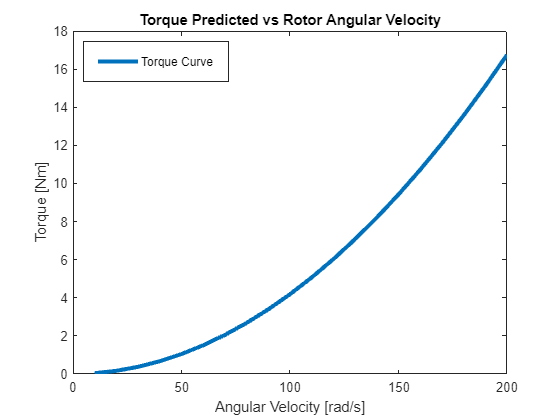

legend("Position", [0.14807,0.80431,0.26105,0.09691])


plot((10:10:200),thrust_speed_curve(1:20), 'linewidth',3)
hold on
% plot((10:10:200),Thrust_function(10:10:200),'--c','linewidth',1.5) %NEEDS TO BE COMMENTED OUT ON FIRST RUN
title("Thrust Predicted vs Rotor Angular Velocity")
xlabel('Angular Velocity [rad/s]');
ylabel('Thrust [Nm]');
hold off

legend(["Thrust Curve","Fitted Curve"])

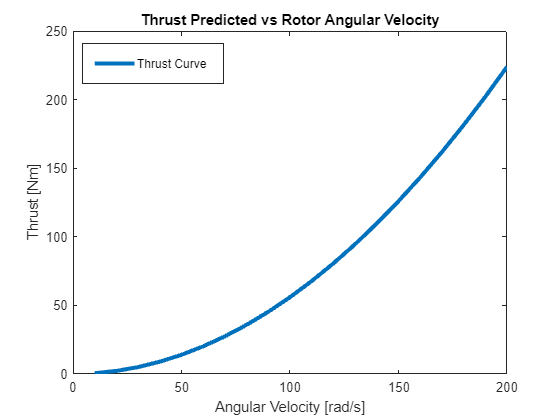


legend("Position", [0.14596,0.80009,0.25474,0.09691])

# Optimising Thrust Positions

Prop_radius = 2.9/2*0.0254 %From inchs to m

Prop_radius = 0.0368

pitch = 0.0254*2.9

pitch = 0.0737

nr_of_blades = 4;
pitch_angle = atand(pitch/(2*Prop_radius*pi))

pitch_angle = 17.6568


chord_of_prop = 0.01;               % 1 cm wide props
Torque_required = 1.55

Torque_required = 1.5500

Thrust_required = zeros(0,90)


Thrust_required =

  0×90 empty double matrix



Thrust_avaliable = zeros(0,90)


Thrust_avaliable =

  0×90 empty double matrix



Omega = 60;
hub_radius = 135/2000

hub_radius = 0.0675

Omega_prop = 2000 % Converts speed to have a max of 48 000 rpm then into rad/s

Omega_prop = 2000

Start = 0.00

Start = 0

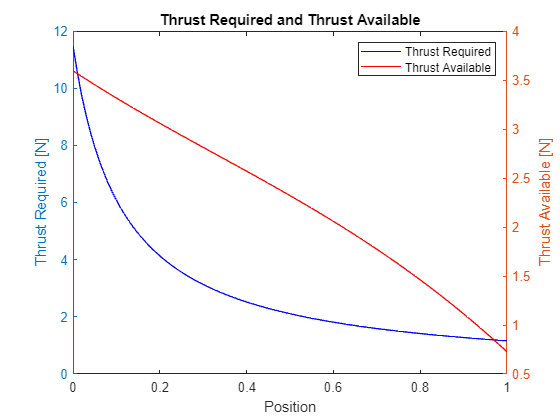

clear position_array
position_array = zeros(1,40);

% for Omega_prop_speed = 1:1:40
%     Omega_prop = Omega_prop_speed*100;
% Position = 1;
for Position = Start:0.01:1
    V0_prop = Omega.*((R*Position)+hub_radius);    
    phi_prop = atand(V0_prop/2/(3./4.*Prop_radius.*Omega_prop));  
    alpha_prop = pitch_angle - phi_prop;
    thrust_from_prop = Thrust(Cl(alpha_prop),rho,Omega_prop,2/3*Prop_radius,chord_of_prop,phi_prop,Cd(alpha_prop), nr_of_blades,V0_prop,2/3*Prop_radius);
    Thrust_avaliable(round(Position/0.01-(Start/0.01-1))) = thrust_from_prop;
    Thrust_required(round(Position/0.01-(Start/0.01-1))) = Torque_required ./ (2.*((R*Position)+hub_radius))  ;
end
Thrust_required;
Thrust_avaliable_standerdised = (Thrust_avaliable - mean(Thrust_avaliable))./std(Thrust_avaliable);
Thrust_required_standerdised = (Thrust_required - mean(Thrust_required))./std(Thrust_required);
optimisation_curve = Thrust_avaliable_standerdised - Thrust_required_standerdised;
gradient = diff(optimisation_curve);

[grad,index] = min(abs(gradient));
Optimum_postition = ((index-0.5).*0.01).*R;

Position = Optimum_postition./R ;
% position_array(round(Omega_prop_speed)) = Position;
% end
% plot(Thrust_required,Thrust_avaliable)
% plot(0.1:0.01:1,Thrust_required)
% hold on
% plot(0.1:0.01:1,Thrust_avaliable)
% hold off

figure;
yyaxis left
plot(Start:0.01:1, Thrust_required, '-b');
ylabel('Thrust Required [N]');

yyaxis right
plot(Start:0.01:1, Thrust_avaliable, '-r');
ylabel('Thrust Available [N]');

xlabel('Position');
% xline(0.365,'--k','linewidth',1)
title('Thrust Required and Thrust Available');
legend('Thrust Required', 'Thrust Available');

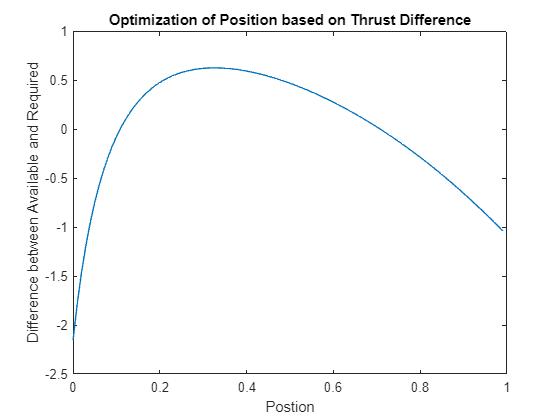



figure;
plot(Start:0.01:0.99, optimisation_curve(1:100));
% hold on
% plot(Start:0.01:0.99,gradient)
% hold off
title('Optimization of Position based on Thrust Difference');
xlabel('Postion');
ylabel('Difference between Available and Required')


% Position = 1

fprintf('Optimum rotor ratio is at %0.3f of the rotor \nFor a rotor size of %0.2f m, the thrust should be placed at %.3f m',Optimum_postition./R,R,Optimum_postition)

Optimum rotor ratio is at 0.325 of the rotor 
For a rotor size of 0.60 m, the thrust should be placed at 0.195 m

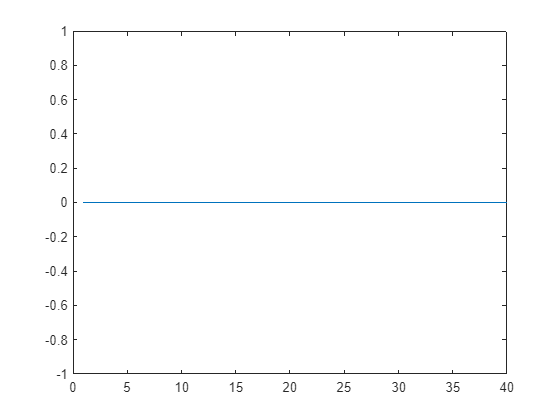

plot(1:1:40,position_array)

## Angle of attack 

interval =0.5

interval = 0.5000

AOA_Vs_Thrust = zeros(1, 14/interval);
omega_AOA_profile = zeros(1, 8)

omega_AOA_profile =      0     0     0     0     0     0     0     0


for omega = 10:10:100
% omega = 30
end_AOA = 45;
for AOA = 5:interval:end_AOA
    theta = AOA;
    thrust_profile = zeros(1,length(r_seg));
    V02 = 0;
    for j = 1:iterations
    alpha = theta - atand(V02/(2./3.*R.*omega));
 
    for i = 1:length(r_seg)

        thrust_profile(i) = Thrust(Cl(alpha),rho,omega,r_seg(i),c,theta-alpha,Cd(alpha), B,V0(i),R/segments); % *0.98 to help account for Tip vortices
        torque_profile(i) = Torque(Cl(alpha),rho,omega,r_seg(i),c,theta-alpha,Cd(alpha), B,V0(i),R/segments);
        thrust_P(j,i)=thrust_profile(i);
        torque_P(j,i)=torque_profile(i);
    end
    total_thrust = sum(thrust_profile);
    if total_thrust < 0
        total_thrust = 0.3.*abs(total_thrust);
    end


    total_torque = sum(torque_profile(4:end));
        CT = total_thrust ./ (pi.*R.^2.*rho.*(omega.*R).^2);
    tip_loss = 1 - sqrt(2.*CT)./2;
    V02 = sqrt(total_thrust.*tip_loss/(pi * R.^2 .* rho.*2));
    if alpha > 16 
    total_thrust =0;
    end
    AOA_Vs_Thrust(AOA/interval + 1)=total_thrust;
    end
end

% AOA_Vs_Thrust(end)/;
omega_AOA_profile(omega/10) = (AOA_Vs_Thrust(60)-AOA_Vs_Thrust(10))/25;

end

0:interval:20

ans =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000   10.5000   11.0000   11.5000   12.0000   12.5000   13.0000   13.5000   14.0000   14.5000   15.0000   15.5000   16.0000   16.5000   17.0000   17.5000   18.0000   18.5000   19.0000   19.5000   20.0000


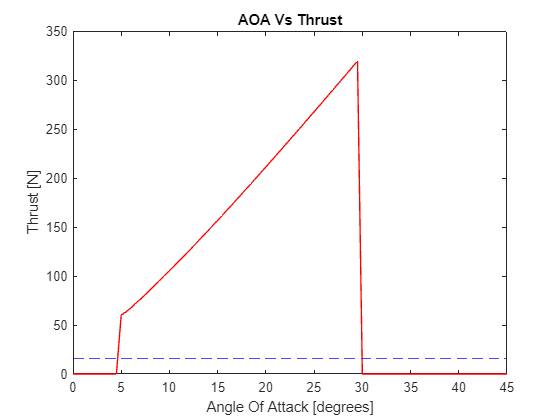

plot(0:interval:end_AOA,AOA_Vs_Thrust,'r') 
xlabel('Angle Of Attack [degrees]');
yline(16,'--b')
ylabel('Thrust [N]');
title('AOA Vs Thrust');

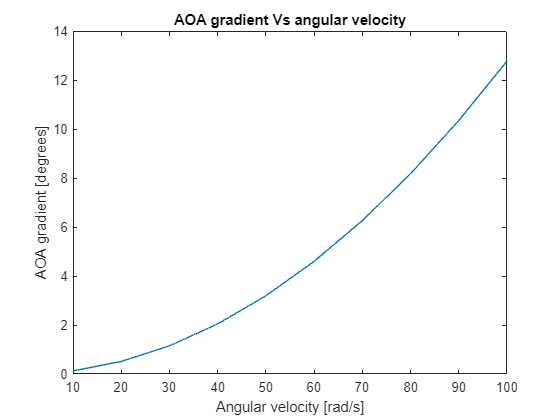


plot( 10:10:100, omega_AOA_profile)
xlabel('Angular velocity [rad/s]');
ylabel('AOA gradient [degrees]');
title('AOA gradient Vs angular velocity');

## Propeller

Prop_radius = 2.9/2*0.0254 %From inchs to m

Prop_radius = 0.0368

pitch = 0.0254*2.9

pitch = 0.0737

% Prop_radius = 0.072/2   %(EFLUP72653BR ) Propeller
% pitch = 0.065 ;         %(EFLUP72653BR)
nr_of_blades = 4;
pitch_angle = atand(pitch/(2*Prop_radius*pi))

pitch_angle = 17.6568

speed = 800;            % Itterates between  start and speed of omega values
prop_thrust_profile= zeros(1,speed/10);
prop_torque_profile= zeros(1,speed/10);
prop_Thrust_p1_coeffcient = zeros(1,speed/10);
prop_Thrust_p2_coefficient =  zeros(1,speed/10);
prop_Thrust_p3_coeffcient =  zeros(1,speed/10);
all_thrust_profiles = zeros(speed/10,speed/10);
all_torque_profiles = zeros(speed/10,speed/10);
start = 10;
xx = (start:10:speed).*2.*pi

xx = 1.0e+03 *

    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221    1.8850    1.9478    2.0106    2.0735    2.1363    2.1991    2.2619    2.3248    2.3876    2.4504    2.5133    2.5761    2.6389    2.7018    2.7646    2.8274    2.8903    2.9531    3.0159    3.0788    3.1416


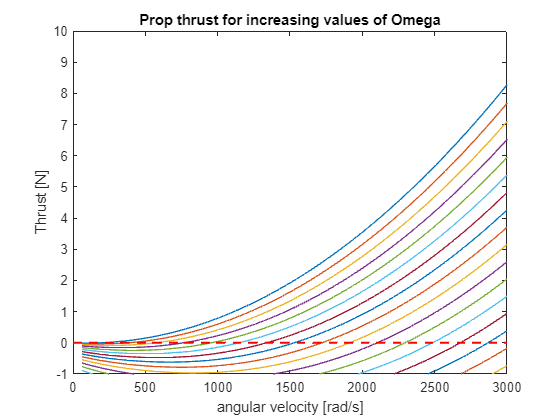



X = [start:10:speed]'.*60;

for Omega_Speed = start:10:speed
for Prop_speeds= start:10:speed
    V0_prop = Omega_Speed.*R*Position;
    Omega_prop = Prop_speeds.*60*pi/30; % Converts speed to have a max of 48 000 rpm then into rad/s
    chord_of_prop = 0.01;               % 1 cm wide props

    phi_prop = atand(V0_prop/(2./3.*Prop_radius.*Omega_prop));  
    
    alpha_prop = pitch_angle - phi_prop;
    thrust_from_prop = Thrust(Cl(alpha_prop),rho,Omega_prop,2/3*Prop_radius,chord_of_prop,phi_prop,Cd(alpha_prop), nr_of_blades,V0_prop,2/3*Prop_radius);

    % if alpha_prop > 16        %% If statment for stalling (above 16 deg)
    %     thrust_from_prop = 0;
    % end

    torque_of_prop = Torque(Cl(alpha_prop),rho,Omega_prop,2/3*Prop_radius,chord_of_prop,phi_prop,Cd(alpha_prop), nr_of_blades,V0_prop,2/3*Prop_radius);
    prop_thrust_profile(Prop_speeds/10) = thrust_from_prop;
    prop_torque_profile(Prop_speeds/10) = torque_of_prop;
    all_thrust_profiles(Omega_Speed/10,Prop_speeds/10)= thrust_from_prop;
    all_torque_profiles(Omega_Speed/10,Prop_speeds/10)= torque_of_prop;

    
end
plot((start:10:speed).*60.*pi/30,prop_thrust_profile)
xlabel('angular velocity [rad/s]');
ylabel('Thrust [N]');
title('Prop thrust for increasing values of Omega');
yline(0, '--r', 'LineWidth', 1.5);
xline(3351,'--b','linewidth',1.5);
ylim([-1,10])
xlim([0,3000])

hold on

FO = fit(xx',prop_thrust_profile', 'poly2');    % Fitting the the thrust profile to a polynomial of degeree 2 (ax^2 + bx + c)
prop_Thrust_p1_coeffcient(Omega_Speed/10) = FO.p1;
prop_Thrust_p2_coefficient(Omega_Speed/10) = FO.p2;
prop_Thrust_p3_coeffcient(Omega_Speed/10) = FO.p3;
end
hold off

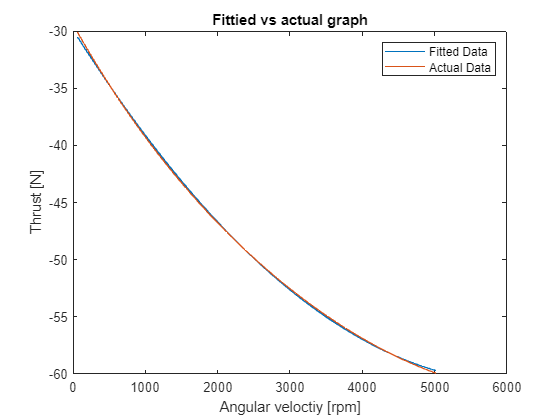


prop_Thrust_p1_coeffcient;
prop_thrust_profile;

Y=FO(xx);
plot(xx,Y)
xlabel('Angular veloctiy [rpm]');
ylabel('Thrust [N]');
title('Fittied vs actual graph');
hold on
plot((start:10:speed)*60.*pi/30,prop_thrust_profile)
legend(["Fitted Data","Actual Data"])
hold off

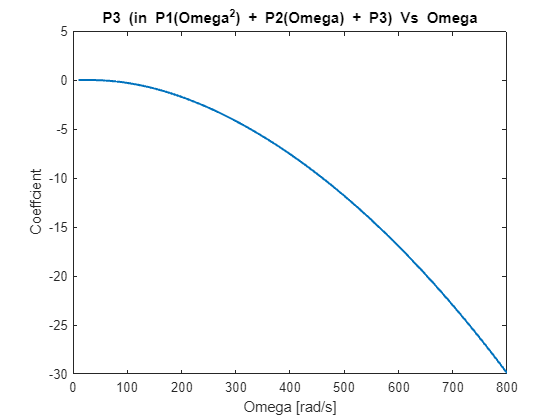

plot(start:10:speed,prop_Thrust_p3_coeffcient, 'linewidth',1.5)
xlabel('Omega [rad/s]');
ylabel('Coeffcient');
title('P3 (in P1(Omega^2) + P2(Omega) + P3) Vs Omega');

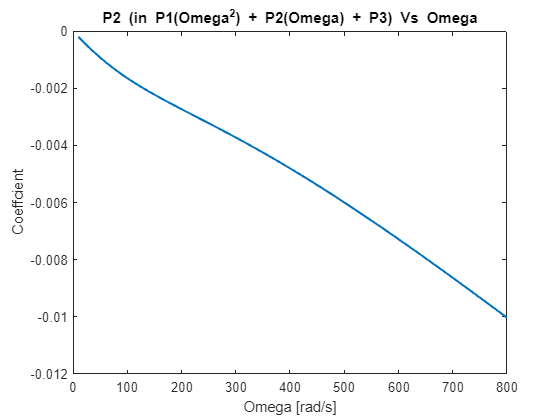


plot(start:10:speed,prop_Thrust_p2_coefficient, 'linewidth',1.5)
xlabel('Omega [rad/s]');
ylabel('Coeffcient');
title('P2 (in P1(Omega^2) + P2(Omega) + P3) Vs Omega');

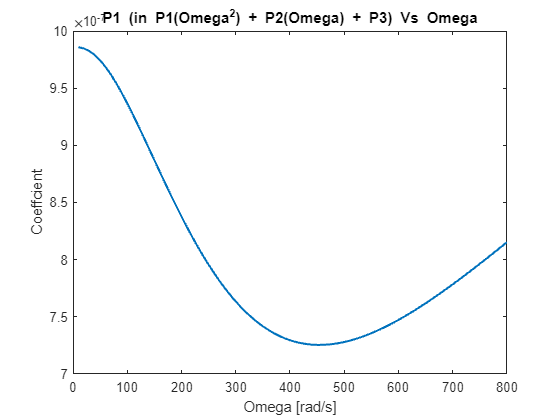


plot(start:10:speed,prop_Thrust_p1_coeffcient, 'linewidth',1.5)
xlabel('Omega [rad/s]');
ylabel('Coeffcient');
title('P1 (in P1(Omega^2) + P2(Omega) + P3) Vs Omega');

% 
% hold on
% 
% FC2 = fit((start:10:speed)',prop_Thrust_p1_coeffcient','poly3')
% YY = FC2((start:10:speed)');
% plot((start:10:speed)',YY)
% legend(["Actual Data","Fitted Data"])
% legend("Position", [0.6524,0.15242,0.22179,0.089378])
% hold off



all_thrust_profiles(4,53)

ans = 8.3126

Omega_prop = 20000.*pi/30

Omega_prop = 2.0944e+03

V0_prop = 40.*(R.*Position+hub_radius)

V0_prop = 10.5000

   phi_prop = atand(V0_prop/(3./4.*Prop_radius.*Omega_prop));  
    
    alpha_prop = pitch_angle - phi_prop

alpha_prop = 7.3698

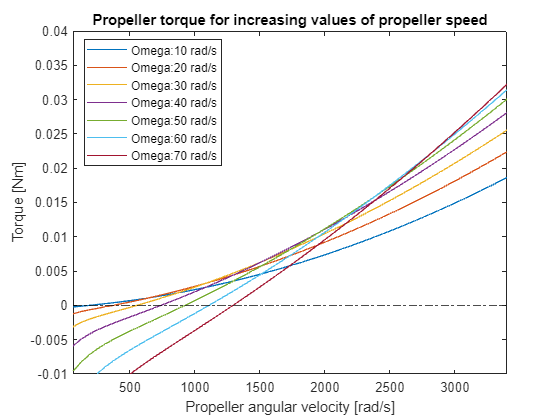

figure;
    plot((start:10:speed).*60.*pi/30,all_torque_profiles(1:7,:)')
    xlabel('Propeller angular velocity [rad/s]');
    yline(0, '-.k','linewidth',0.1)
ylabel('Torque [Nm]');
title('Propeller torque for increasing values of propeller speed');
legend(["Omega:10 rad/s","Omega:20 rad/s","Omega:30 rad/s","Omega:40 rad/s","Omega:50 rad/s","Omega:60 rad/s","Omega:70 rad/s"])
legend("Position", [0.15059,0.60437,0.24643,0.30357])
ylim([-.01,.04])
xlim([10.*60.*pi/30,3400])

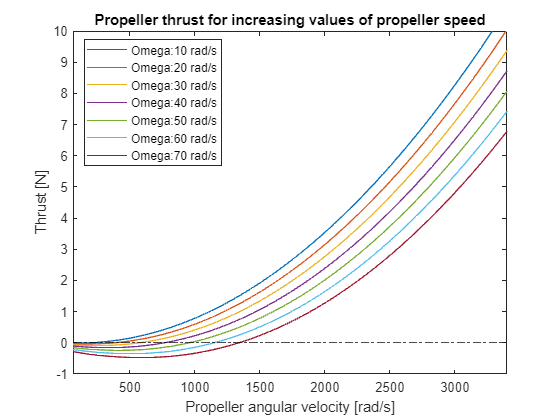



plot((start:10:speed).*60.*pi/30,all_thrust_profiles(1:7,:)')
yline(0, '-.k','linewidth',0.1)
xlabel('Propeller angular velocity [rad/s]');
ylabel('Thrust [N]');
title('Propeller thrust for increasing values of propeller speed');
legend(["Omega:10 rad/s","Omega:20 rad/s","Omega:30 rad/s","Omega:40 rad/s","Omega:50 rad/s","Omega:60 rad/s","Omega:70 rad/s"])
legend("Position", [0.15059,0.60437,0.24643,0.30357])
ylim([-1,10])
xlim([10.*60.*pi/30,3400])

## Curve Fitting

X = [(10:10:800)]';
Thrust_function = fit(X,thrust_speed_curve', 'power1')

Thrust_function =      General model Power1:
     Thrust_function(x) = a*x^b
     Coefficients (with 95% confidence bounds):
       a =    0.005598  (0.005598, 0.005598)
       b =           2  (2, 2)

Torque_function = fit(X,torque_speed_curve','power1')

Torque_function =      General model Power1:
     Torque_function(x) = a*x^b
     Coefficients (with 95% confidence bounds):
       a =   0.0004187  (0.0004187, 0.0004187)
       b =           2  (2, 2)

prop_A_coef = fit((start:10:speed)',prop_Thrust_p1_coeffcient','poly3');
prop_B_coef = fit((start:10:speed)',prop_Thrust_p2_coefficient','poly3');
prop_C_coef = fit((start:10:speed)',prop_Thrust_p3_coeffcient','poly2');
FO = fit(X.*60,prop_thrust_profile', 'poly2');

# LaTeX Conversion

fprintf(['\\left((%0.3f\\times 10^{%d})\\omega ^3 + (%0.3f\\times 10^{%d})\\omega ^2 + (%0.3f\\times 10^{%d})\\omega \\right.\\notag\\\\\n' ...
    '&\\left. + (%0.3f\\times 10^{%d})\\right)\\omega_{prop}^2 + \\left((%0.3f\\times 10^{%d})\\omega^2+(%0.3f\\times 10^{%d})\\omega^2 \\right. \\notag\\\\\n' ...
    '&\\left. + (%0.3f\\times 10^{%d})\\omega  %0.4f \\right)\\omega_{prop}+\\left( (%0.3f\\times 10^{%d})\\omega^2 \\right. \\notag\\\\\n' ...
    '&\\left.+ (%0.3f\\times 10^{%d})\\omega +%0.4f\\right) \\label{eq: prop_thrust}'], ...
    coef_finder(prop_A_coef.p1),exp_finder(prop_A_coef.p1),coef_finder(prop_A_coef.p2),exp_finder(prop_A_coef.p2),coef_finder(prop_A_coef.p3),exp_finder(prop_A_coef.p3),coef_finder(prop_A_coef.p4),exp_finder(prop_A_coef.p4), ...
    coef_finder(prop_B_coef.p1),exp_finder(prop_B_coef.p1),coef_finder(prop_B_coef.p2),exp_finder(prop_B_coef.p2),coef_finder(prop_B_coef.p3),exp_finder(prop_B_coef.p3),prop_B_coef.p4, ...
    coef_finder(prop_C_coef.p1),exp_finder(prop_C_coef.p1),coef_finder(prop_C_coef.p2),exp_finder(prop_C_coef.p2),prop_C_coef.p3);

\left((-2.500\times 10^{-16})\omega ^3 + (1.517\times 10^{-12})\omega ^2 + (-1.314\times 10^{-9})\omega \right.\notag\\
&\left. + (1.037\times 10^{-6})\right)\omega_{prop}^2 + \left((-7.806\times 10^{-12})\omega^2+(7.144\times 10^{-9})\omega^2 \right. \notag\\
&\left. + (-1.301\times 10^{-5})\omega  -0.0003 \right)\omega_{prop}+\left( (-4.593\times 10^{-5})\omega^2 \right. \notag\\
&\left.+ (-1.006\times 10^{-3})\omega +0.2227\right) \label{eq: prop_thrust}

## Speed for thrust calculator

% Enter required thrust below 
Thrust_req = 20

Thrust_req = 20




omega_for_thrust = @(x) (x./Thrust_function.a).^(1/Thrust_function.b);              % Converts Thrust to Omega value
Torque_for_thrust = @(x) Torque_function.a.*omega_for_thrust(x).^Torque_function.b; % converts Thrust into torque
Thrust_requried = Torque_for_thrust(Thrust_req)/(2*(R.*Position+hub_radius));
omega= omega_for_thrust(Thrust_req);
prop_speed_function = @(x) prop_A_coef(omega).*x.^2 + prop_B_coef(omega).*x + prop_C_coef(omega) - Thrust_requried;
prop_speed_function_quad(1) = (-prop_B_coef(omega) + sqrt(prop_B_coef(omega).^2 - 4.*prop_A_coef(omega).*(prop_C_coef(omega)- Thrust_requried) ))./(2.*prop_A_coef(omega));
prop_speed_function_quad(2) = (-prop_B_coef(omega) - sqrt(prop_B_coef(omega).^2 - 4.*prop_A_coef(omega).*(prop_C_coef(omega)- Thrust_requried) ))./(2.*prop_A_coef(omega));
prop_speed_quad = max(prop_speed_function_quad)

prop_speed_quad = 2.3579e+03

% prop_A_coef(omega)                        a
% prop_B_coef(omega)                        b
% (prop_C_coef(omega)- Thrust_requried)     c   
% fplot(prop_speed_function,[0,5000])
prop_speed =fzero(prop_speed_function,200.*Thrust_req).*30/pi

prop_speed = 2.2516e+04


fprintf('Rotor speed: %.2f rpm (%.2f rad/s)',omega.*30/pi,omega)

Rotor speed: 570.77 rpm (59.77 rad/s)

fprintf('Torque required: %.2f Nm',Torque_for_thrust(Thrust_req))

Torque required: 1.50 Nm

fprintf('Thrust required: %.2f N',Thrust_requried)

Thrust required: 2.85 N

fprintf('Prop speed: %.2f rpm (%.2f rad/s)',prop_speed, prop_speed.*pi/30)

Prop speed: 22516.16 rpm (2357.89 rad/s)

fprintf('Tip speed: %.2f m/s',omega*R)

Tip speed: 35.86 m/s

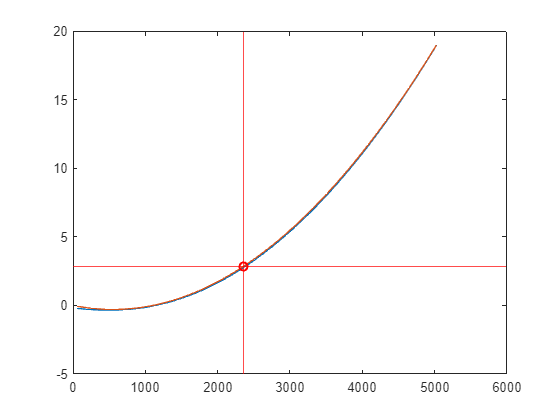


X = [(10:10:800)]';
plot(X.*pi/30.*60,all_thrust_profiles(round(omega/10),:))
hold on
plot(X.*pi/30.*60,prop_speed_function(X.*60.*pi/30)+Thrust_requried)
plot(prop_speed.*pi/30,Thrust_requried,'or', 'linewidth', 1.5)
hold off
yline(Thrust_requried,'r')
xline(prop_speed.*pi/30, 'r')

# Functions

### Thrust produced

function thrust = Thrust(Cl,rho,omega,r,c,phi,Cd,B,V0,dr_segment)
    V1 = sqrt((omega.*r).^2 + (V0).^2);
    thrust = 1/2 .* rho .* V1.^2 .* (Cl .* cosd(phi) - Cd .* sind(phi)) .* B .* c .* dr_segment;
end

### Torque produced

function torque = Torque(Cl,rho,omega,r,c,phi,Cd,B,V0,dr_segment)
    V1 = sqrt((omega.*r).^2 + (V0).^2);
    torque = 1/2 .* rho .* V1.^2 .* (Cd .* cosd(phi) + Cl .* sind(phi)) .* B .* c .* dr_segment .* r;
end

### Crossectional area

function area_of_NACA = dr(c,t)
    NACA_f = @(x) 5.*t.*(0.2969.*sqrt(x) - 0.126.*x - 0.3156.*x.^2 + 0.2843.*x.^3 - 0.1015.*x.^4);
    area_of_NACA = 2*integral(NACA_f,0,c);
end

### Lift produced for defined alpha

function lift_coefficent = Cl(alpha)
    % lift_coefficent = 1./10 .* alpha + 0;
    lift_coefficent = 3./25 .* alpha + 0.6;

end

### Drag produced for defined alpha

function drag_coeffcient = Cd(alpha)
    % drag_coeffcient = 1.6e-4 .* alpha.^2 +0.005;
    drag_coeffcient = 3.8e-4 .* alpha.^2 +0.02;

end

### Estimate rotational speed to produce a given torque

function omega = Omega_Estimate(Cl,rho,total_drag,c,phi,Cd,B,V0,L)
    V1_squared = 2.* total_drag / (rho * (Cd * cosd(phi) + Cl * sind(phi)) * B * c.*L*L);
    omega = sqrt((V1_squared) - (V0).^2)/(L);
end

### Estimate rotational speed to produce a given thrust


function omega_thrust = Omega_Thrust_Estimate(Cl,rho,total_thrust,c,phi,Cd,B,V0,L,omega)
    V1_squared = 2.* total_thrust / (rho * (Cl * cosd(phi) - Cd * sind(phi)) * B * c *L);
    if V1_squared < V0^2
        omega_thrust =2*omega;
    else
        omega_thrust = sqrt((V1_squared) - (V0).^2)/(L);
    end
end

#### Return coeffcient value

function coef = coef_finder(number)
    coef = 10^mod(log10(abs(number)),1).*sign(number);
end

### Exponential Finder

function exp = exp_finder(number)
    exp = floor(log10(abs(number)));
end

### Estimate speed of tip thrust for required torque

function Thrust_Requirements(required_thrust,R)
    X = [(10:10:800)]';
    Thrust_function = fit(X,thrust_speed_curve', 'power1')
    Torque_function = fit(X,torque_speed_curve','power1')
    prop_A_coef = fit((start:10:speed)',prop_Thrust_p1_coeffcient','poly6');
    prop_B_coef = fit((start:10:speed)',prop_Thrust_p2_coefficient','poly6');
    prop_C_coef = fit((start:10:speed)',prop_Thrust_p3_coeffcient','poly6');
    FO = fit(X.*60,prop_thrust_profile', 'poly2');


    omega_for_thrust = @(x) (x./Thrust_function.a).^(1/Thrust_function.b);
    Torque_for_thrust = @(x) Torque_function.a.*omega_for_thrust(x).^Torque_function.b;
    omega= omega_for_thrust(Thrust_req);
    omega.*30/pi;
    Thrust_requried = Torque_for_thrust(Thrust_req)/R
    fprintf(['Speed in RPM:%.2f \n',omega.*30/pi ...
        'Thrust required:%.2f',Thrust_requried])
    prop_speed_function = @(x) prop_A_coef(omega).*x.^2 + prop_B_coef(omega).*x + prop_C_coef(omega) - Thrust_requried;
    % fplot(prop_speed_function,[0,5000])
    fzero(prop_speed_function,3000).*30/pil
end